# Laboratory exercises: continuous-time speed control of a DC motor

Riccardo Antonello ([antonello@dei.unipd.it](mailto:antonello@dei.unipd.it)) and Luca Schenato ([schenato@dei.unipd.it](mailto:schenato@dei.unipd.it))

March 25, 2021

Dept. of Information Engineering, University of Padova, Italy

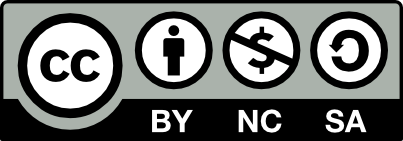

*This work is licensed under a Creative Commons Attribution-NonCommercial-ShareAlike 4.0 International license.*

## Exercise 2: simulation of a continuous-time speed control system for a DC motor using the CST

Consider the continuous-time speed control system for a DC motor illustrated in Fig. 1, where 


$$P'(s) = \frac{\Omega(s)}{U_a(s)} = \frac{k_m}{T_m s + 1}\,,\qquad
P(s) = \frac{\Theta(s)}{U_a(s)} = \frac{1}{s}\,P'(s)\,,
\qquad
k_m = 5.2\,,\quad
T_m = 0.03$$


are the continuous-time transfer functions of the DC motor, from the armature voltage $u_a\,\mathrm{[V]}$ to the shaft speed $\omega\,\mathrm{[rad/s]}$ and position $\vartheta\,\mathrm{[rad]}$, $C(s)$ is the transfer function of the continuous--time controller, and $H(s)$ is the transfer function of a continuous-time ``real'' derivative filter used to get a speed estimate $\omega_m(t)$ from the position measurement $\vartheta_m(t)$. 

The inputs $\omega^*(t)$, $d(t)$ and $n(t)$ are respectively the speed reference, the load disturbance (e.g. a voltage equivalent of a disturbance torque applied to the motor), and the output noise of the position sensor.

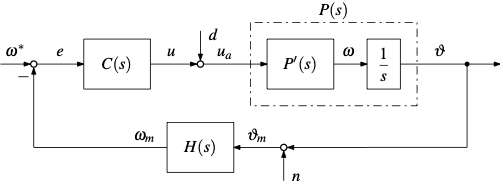

**Figura 1**: Schema di controllo di velocità di un motore elettrico in corrente continua.

By using only the routines of the Control System Toolbox (CST), do the following points:

1) Consider a purely proportional (P) controller with gain $K_P$; for the speed filter $H(s)$, consider the filter $H_2(s)$ defined in the exercise 1. Draw the root locus of the control system with input $\omega^*(t)$ and output $\omega_m(t)$ as the proportional gain $K_P$ varies from $0$ to $+\infty$ (Note: when sketching the root locus, the *loop transfer function* must be considered).

Then, identify the critical gain $K_P^*$ beyond which the control system become unstable.

*Solution.*

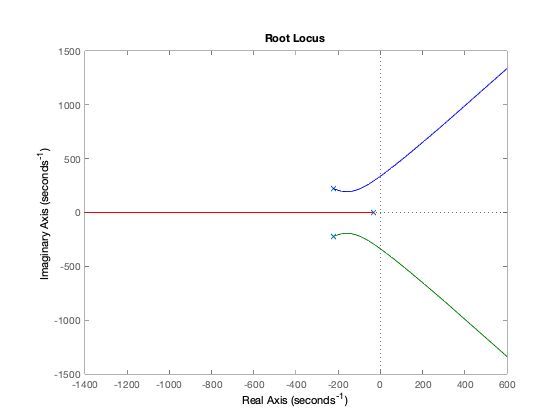

%   conversion gains
rads2rpm = 60/2/pi;
rpm2rads = 2*pi/60;

%   plant parameters
km = 5.2;
Tm = 0.03;

%   plant tf
sysP1 = tf(km,[Tm, 1]);
sysI = tf(1,[1,0]);
sysP = sysP1 * sysI;

%   continuous-time 2nd order HPF
fc = 50;            %   cut-off freq
wc = 2*pi*fc;
dc = 1/sqrt(2);     %   damping factor

numH = [wc^2, 0];
denH = [1, 2*dc*wc, wc^2];
sysH = tf(numH, denH);

%   loop tf (with unitary P gain)
sysL = sysP*sysH;

%   root locus wrt P gain
figure;
rlocus(sysL);

The critical gain is equal to:

%   critical gain
kc = margin(sysL)

kc = 2.9767

2) Set the proportional gain equal to $K_P = K_P^*/4$. Determine the actual speed $\omega(t)$, the measured speed $\omega_m(t)$, and the command $u(t)$ responses to a $300\,\mathrm{rpm}$ speed step reference, over a $0.3\,\mathrm{s}$ time range. Show the results on a MATLAB figure, and determine the speed step response parameters (i.e. rise time, settling time at $5\%$, overshoot).

Is the P controller capable of achieving zero steady-state tracking error (of the step reference input) ?

*Solution*.

%   P gain
kp = kc/4;
sysC = kp

sysC = 0.7442


%   closed-loop tf from ref (w^*) to actual speed (w)
sysT = feedback(sysC*sysP1, sysI*sysH);
sysT = minreal(sysT)


sysT =
 
      129 s^2 + 5.731e04 s + 1.273e07
  ---------------------------------------
  s^3 + 477.6 s^2 + 1.135e05 s + 1.602e07
 
Continuous-time transfer function.




%   closed-loop tf from ref (w^*) to measured speed (w_m)
sysCPHS = feedback(sysC*sysP*sysH, 1);
sysCPHS = minreal(sysCPHS)


sysCPHS =
 
                 1.273e07
  ---------------------------------------
  s^3 + 477.6 s^2 + 1.135e05 s + 1.602e07
 
Continuous-time transfer function.




%   closed-loop tf from ref (w^*) to control command (u)
sysCS = feedback(sysC, sysP*sysH);
sysCS = minreal(sysCS)


sysCS =
 
  0.7442 s^3 + 355.4 s^2 + 8.447e04 s + 2.448e06
  ----------------------------------------------
     s^3 + 477.6 s^2 + 1.135e05 s + 1.602e07
 
Continuous-time transfer function.



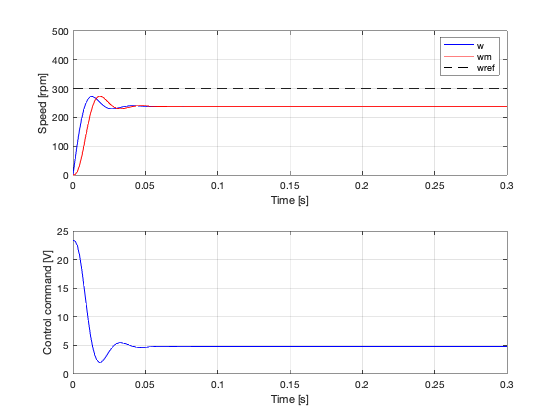


%   time array
t = linspace(0, 0.3, 200);

%   actual speed response 
opt = stepDataOptions('InputOffset', 0, 'StepAmplitude', 300*rpm2rads);
w = step(sysT, t, opt);

%   measured speed response
wm = step(sysCPHS, t, opt);

%   control command response
u = step(sysCS, t, opt);

%   plot results
figure; 
subplot(2,1,1)
plot(t, w*rads2rpm, 'b');
hold on;
plot(t, wm*rads2rpm, 'r');
plot([t(1), t(end)], [300, 300], 'k--');
legend('w', 'wm', 'wref');
grid on;
xlabel('Time [s]');
ylabel('Speed [rpm]');
ylim([0, 500]);

subplot(2,1,2);
plot(t, u, 'b');
grid on;
xlabel('Time [s]');
ylabel('Control command [V]');

Step response parameters:

stepinfo(w, t, 'SettlingTimeThreshold', 0.05)

ans = struct with fields:
        RiseTime: 0.0062
    SettlingTime: 0.0190
     SettlingMin: 23.9494
     SettlingMax: 28.5431
       Overshoot: 14.3342
      Undershoot: 0
            Peak: 28.5431
        PeakTime: 0.0136


The P controller is unable to guarantee perfect steady-state tracking of a constant set-point. 

3) Consider now a continuous-time proportional--integral (PI) controller of the type:


$$C(s) = \frac{U(s)}{E(s)} = K_P\,\frac{s + 100}{s}$$


Repeat points 1 and 2. Is the PI controller capable of achieving zero steady-state tracking error ?

*Solution*.

Root locus sketching:

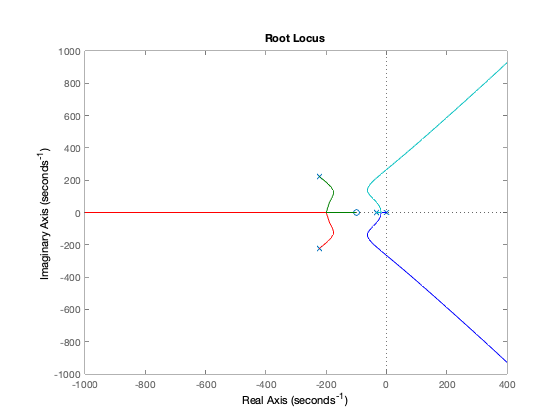

%   PI controller (with unitary P gain)
sysC1 = tf([1, 100], [1, 0]); 

%   loop tf (with unitary P gain)
sysL = sysC1*sysP*sysH;

%   root locus with PI controller
figure;
rlocus(sysL);

The critical gain $K_P^*$ is equal to:

%   critical gain
kc = margin(sysL)

kc = 1.7718

Step responses with $K_P = K_P^*/4$:

%   P gain
kp = kc/4

kp = 0.4429


%   PI controller with selected P gain
sysC = kp * sysC1;

%   closed-loop tf from ref (w^*) to actual speed (w)
sysT = feedback(sysC*sysP1, sysI*sysH);
sysT = minreal(sysT)


sysT =
 
     76.78 s^3 + 4.179e04 s^2 + 1.099e07 s + 7.578e08
  ------------------------------------------------------
  s^4 + 477.6 s^3 + 1.135e05 s^2 + 1.087e07 s + 7.578e08
 
Continuous-time transfer function.




%   closed-loop tf from ref (w^*) to measured speed (w_m)
sysCPHS = feedback(sysC*sysP*sysH, 1);
sysCPHS = minreal(sysCPHS)


sysCPHS =
 
                  7.578e06 s + 7.578e08
  ------------------------------------------------------
  s^4 + 477.6 s^3 + 1.135e05 s^2 + 1.087e07 s + 7.578e08
 
Continuous-time transfer function.




%   closed-loop tf from ref (w^*) to control command (u)
sysCS = feedback(sysC, sysP*sysH);
sysCS = minreal(sysCS)


sysCS =
 
  0.4429 s^4 + 255.9 s^3 + 7.143e04 s^2 + 6.485e06 s + 1.457e08
  -------------------------------------------------------------
     s^4 + 477.6 s^3 + 1.135e05 s^2 + 1.087e07 s + 7.578e08
 
Continuous-time transfer function.



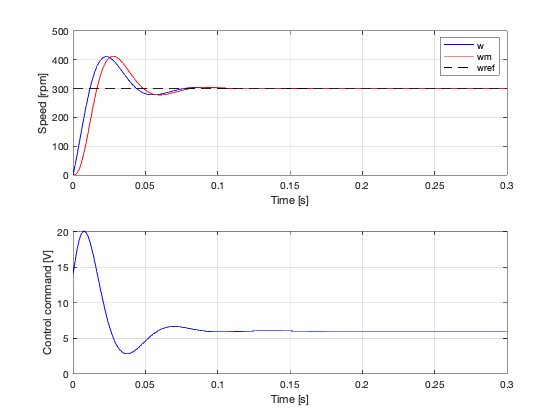


%   actual speed response 
opt = stepDataOptions('InputOffset', 0, 'StepAmplitude', 300*rpm2rads);
w = step(sysT, t, opt);

%   measured speed response
wm = step(sysCPHS, t, opt);

%   control command response
u = step(sysCS, t, opt);

%   plot results
figure; 
subplot(2,1,1)
plot(t, w*rads2rpm, 'b');
hold on;
plot(t, wm*rads2rpm, 'r');
plot([t(1), t(end)], [300, 300], 'k--');
legend('w', 'wm', 'wref');
grid on;
xlabel('Time [s]');
ylabel('Speed [rpm]');
ylim([0, 500]);

subplot(2,1,2);
plot(t, u, 'b');
grid on;
xlabel('Time [s]');
ylabel('Control command [V]');

Step response parameters:

stepinfo(w, t, 'SettlingTimeThreshold', 0.05)

ans = struct with fields:
        RiseTime: 0.0091
    SettlingTime: 0.0640
     SettlingMin: 28.7474
     SettlingMax: 43.0159
       Overshoot: 36.9240
      Undershoot: 0
            Peak: 43.0159
        PeakTime: 0.0226


The PI controller guarantees perfect steady-state tracking of a constant set-point. 